clear all

% Import Data
arduinoData = importdata("C:\Users\tjade\Downloads\DCF_AngleTest_20Deg.txt");

% Sensor Calibration
leftData = importdata("C:\Users\tjade\Downloads\DCF_Calibration_Test_Left.txt");
rightData = importdata("C:\Users\tjade\Downloads\DCF_Calibration_Test_Right.txt");
factors = calibration(leftData, rightData);

% Read Axis Data
x1Axis = smoothdata(transpose(arduinoData(:,3)));
y1Axis = smoothdata(transpose(arduinoData(:,1)));
z1Axis = smoothdata(transpose(arduinoData(:,2)));
x2Axis = smoothdata(transpose(arduinoData(:,6)*(1+factors(1))));
y2Axis = smoothdata(transpose(arduinoData(:,4)*(1+factors(2))));
z2Axis = smoothdata(transpose(arduinoData(:,5)*(factors(3)-1)));

% Manipulate Axis Data
[rows, cols] = size(arduinoData);
magB1 = sqrt(x1Axis.^2 + y1Axis.^2);
magB2 = sqrt(x2Axis.^2 + y2Axis.^2);
avgMag = (magB1 + magB2)./2;
angleOfAttack = atan((magB1./magB2)).*(180/pi) - 45;
x = 1:rows;
figure(1)

%Plot Axis Data
% Magnetic Field Deflection by Component
plot(x, x1Axis, x, y1Axis, x, x2Axis, x, y2Axis)
title('Magnetic Field Deflection(Component Wise)')
xlabel('Time')
ylabel('Magnetic Field (Bx, By, Bz)')
legend('Bx1', 'By1', 'Bx2', 'By2')

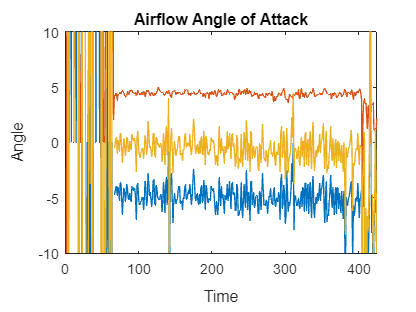


% Magnetic Field Magnitude
plot(x, magB1, x, magB2)
title('Magnetic Field Magnitudes')
xlabel('Time')
ylabel('Magnetic Field (B1, B2)')
legend('B1', 'B2')

% Averaged Magnetic Field
plot(x, avgMag)
title('Averaged Magnetic Field Deflection(Magnitude)')
xlabel('Time')
ylabel('Magnetic Field')


% Airflow Direction
plot(x, angleOfAttack)
title('Airflow Angle of Attack')
xlabel('Time')
ylabel('Angle')
ylim([-100  100])

function factors = calibration(leftData, rightData)
    xLeft = transpose(leftData(:, 3));
    yLeft = transpose(leftData(:, 1));
    zLeft = transpose(leftData(:, 2));
    xRight = transpose(rightData(:, 6));
    yRight = transpose(rightData(:, 4));
    zRight = transpose(rightData(:, 5));
    
    sensor1x = mean(xLeft);
    sensor1y = mean(yLeft);
    sensor1z = mean(zLeft);
    
    sensor2x = mean(xRight);
    sensor2y = mean(yRight);
    sensor2z = mean(zRight);
    
    factorX = abs(sensor2x/sensor1x);
    factorY = abs(sensor2y/sensor1y);
    factorZ = abs(sensor2z/sensor1z);
    
    xRight = mean(xRight*factorX);
    yRight = mean(yRight*factorY);
    zRight = mean(zRight*factorZ);

    newMean = [xLeft, yLeft, zLeft, xRight, yRight, zRight];
    factors = [factorX, factorY, factorZ];
   return
end